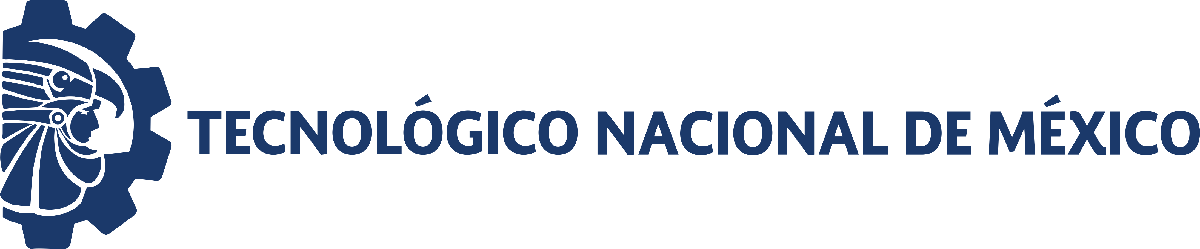                                 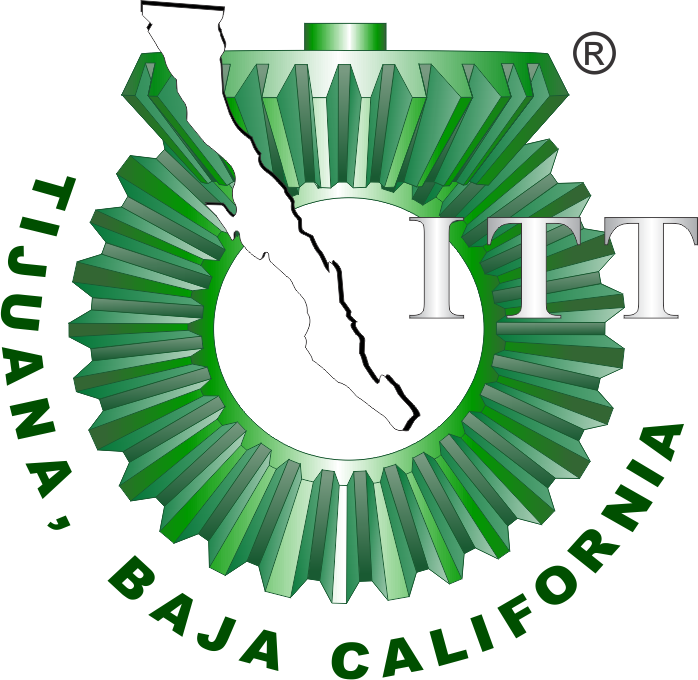

# Práctica tres: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

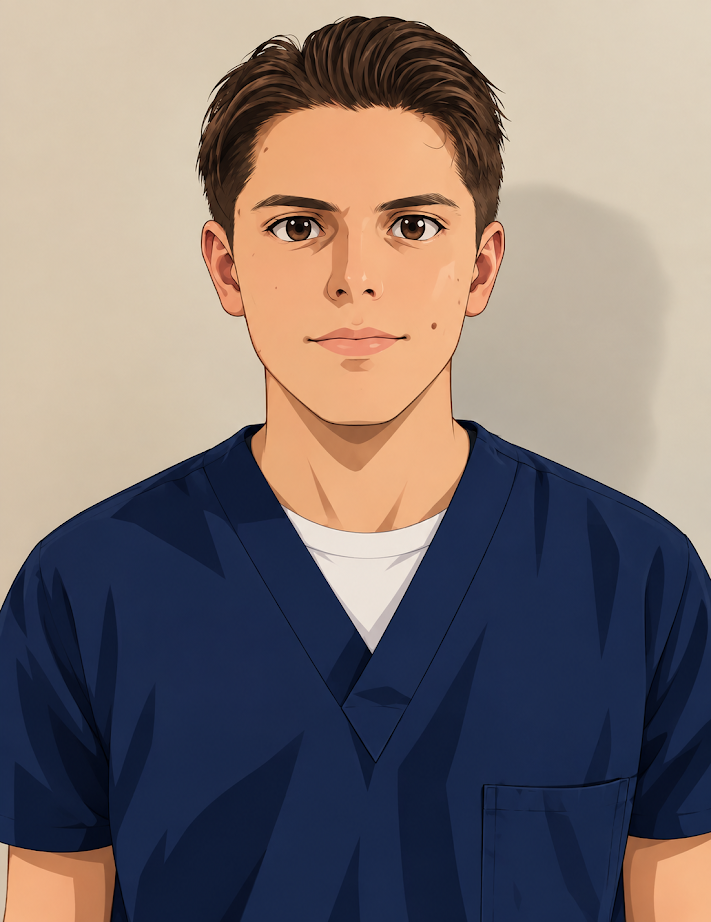

Nombre del alumno: Diego Macias Armenta

Número de control: 23212212

Correo institucional: **l23212212@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc;clear;close all;warning('off','all')
file = 'Practica3';
open_system(file);
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta al impulso unitario

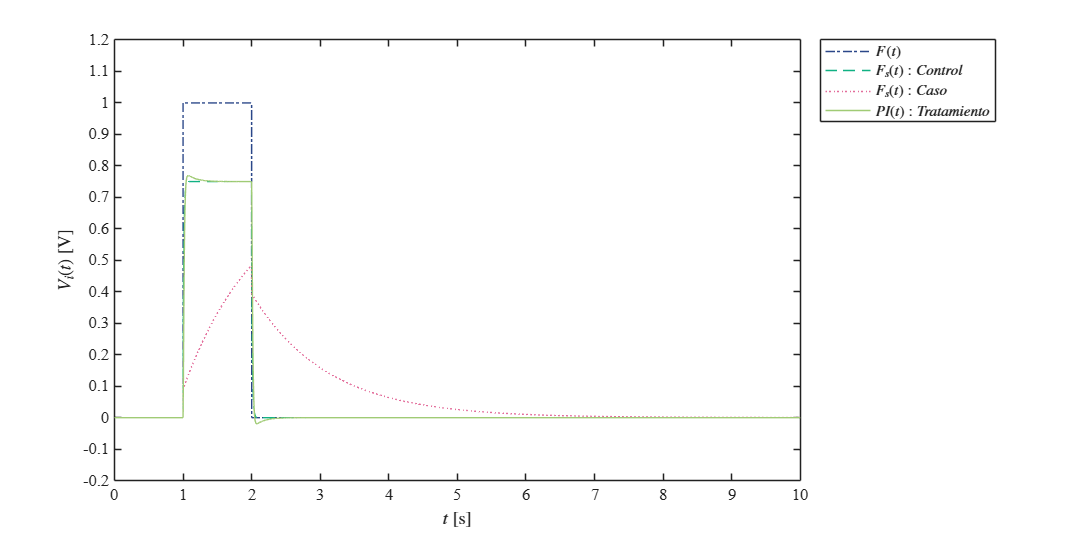

X = sim(file,parameters);
t = X.t;F = X.F;Fsx = X.Fsx;Fsy = X.Fsy;PID = X.PID;
plotsignals(t,F,Fsx,Fsy,PID,'Caso');

## Función: Respuestas de la simulación


function plotsignals(t,F,Fsx,Fsy,PID,signal)

if isa(t,'timeseries')
    t = t.Data;
end

if isa(F,'timeseries')
    F = F.Data;
end

if isa(Fsx,'timeseries')
    Fsx = Fsx.Data;
end

if isa(Fsy,'timeseries')
    Fsy = Fsy.Data;
end

if isa(PID,'timeseries')
    PID = PID.Data;
end

t = t(:);
F = F(:);
Fsx = Fsx(:);
Fsy = Fsy(:);
PID = PID(:);

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])

set(gca,'fontname','times new roman','fontsize',11)

hold on;
grid off;
box on;

clr1 = [43, 71, 137] / 255;
clr2 = [16, 177, 131] / 255;
clr3 = [227, 109, 155] / 255;
clr4 = [160, 203, 117] / 255;

order = [clr1;clr2;clr3;clr4];
colororder(order)

plot(t,F,'-.',t,Fsx,'--',t,Fsy,':',t,PID,'-','LineWidth',0.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));

L = legend('$F(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$','$PI(t): Tratamiento$');

set(L,'interpreter','latex','location','northeastoutside','orientation','vertical');

xlabel('$t$ [s]','Interpreter','latex')
ylabel('$V_i(t)$ [V]','Interpreter','latex')

xlim([0 10]);
xticks(0:1:10);

ylim([-0.2 1.2]);
yticks(-0.2:0.1:1.2);

exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')

end


